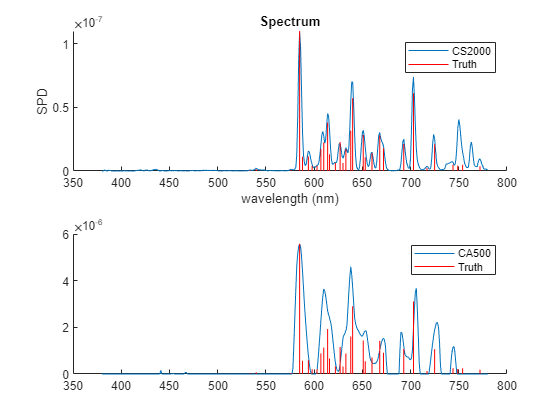

% read CS2000
load('neon_cs2000.mat','mea')
max_cs2000 = max(mea.amplitude);

% read CA500
load('neon_ca500.mat','neon_ca500')
max_ca500 = max(neon_ca500);

% truth
load('truth.mat','truth')
wl = truth(:,1);
wl2 = round(wl);
amp = truth(:,2);
spec = zeros(1,1200);
spec(wl2) = amp;
spec = spec(1,380:780);

% plot
tiledlayout('flow')

nexttile
hold on
mea.plot
for i = 380:780
    line([i i],[0 spec(1,i-380+1)*max_cs2000],'Color','r')
end
legend('CS2000','Truth')

nexttile
hold on
plot(380:780,neon_ca500)
for i = 380:780
    line([i i],[0 spec(1,i-380+1)*max_ca500],'Color','r')
end
legend('CA500','Truth')